clc
clear

k=160000;
c=1000;
m=280;
q=800;

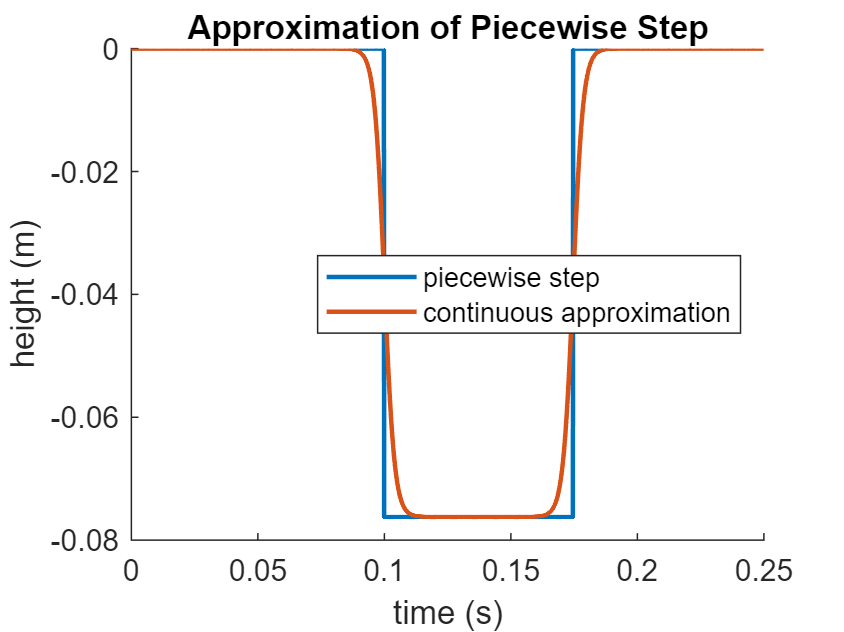

t=(0:15000)*0.0001;
lambda=500;

step1=sigmoid(t,0.1,lambda);
step2=sigmoid(t,0.1746,lambda);

truestep=zeros(15000,1);
truestep(ceil(15000*0.1/1.5):ceil(15000*0.1746/1.5))=-0.0762;

h=(step2-step1)*0.0762;

figure
hold on
plot(t(1:2500),truestep(1:2500),'LineWidth',1.5);
plot(t(1:2500),h(1:2500),'LineWidth',1.5);
hold off
title('Approximation of Piecewise Step')
legend('piecewise step','continuous approximation','Location','east')
xlabel('time (s)')
ylabel('height (m)')


pothole=timeseries(h,t);
save pothole.mat -v7.3 pothole
clear lambda step1 step2 h t pothole